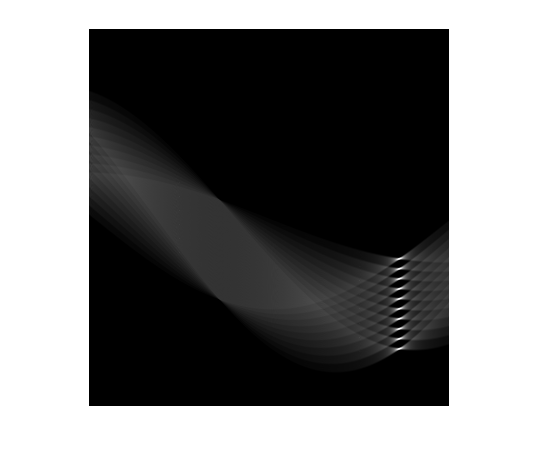

% Part 1 Hough transform
 
 Image1a = imread('Image1a.tif');
 Image1b = imread('Image1b.tif');
 
 %Hough transformation
 [H_a, teta_a, ro_a] = hough(Image1a, 'Rhoresolution', 5, 'Theta', -90:0.5:89.5);
 [H_b, teta_b, ro_b] = hough(Image1b, 'Rhoresolution', 5, 'Theta', -90:0.5:89.5);

% problem 1

 MaxValue_a = max(H_a(:));
 MinValue_a = min(H_a(:));
 
 MaxValue_b = max(H_b(:));
 MinValue_b = min(H_b(:));
 
 H1 = (H_a - MinValue_a)/(MaxValue_a - MinValue_a);
 imshow(H1)

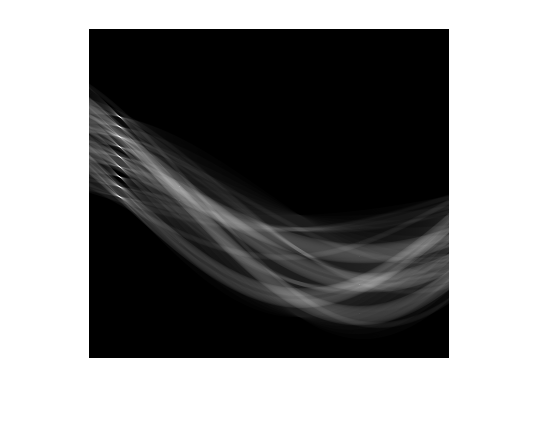

 
 H2 = (H_b - MinValue_b)/(MaxValue_b - MinValue_b);
 imshow(H2)

% imwrite(H1, 'H1.png')

% Problem 2
 [r, t] = find(H_a == max(H_a(:)));
 [r_b, t_b] = find(H_b == max(H_b(:)));
 angle_a = teta_a(t)

angle_a =     65    65


 angle_b = teta_b(t_b)

angle_b = -75

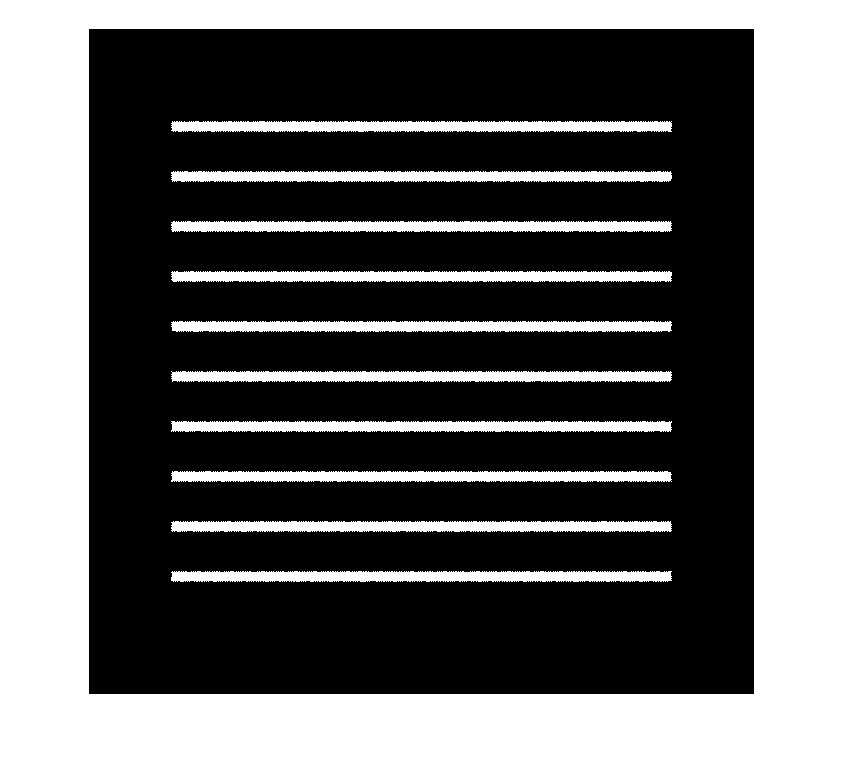


% Problem 3-4
 Image1a_rotated = imrotate(Image1a, -25, 'bicubic', 'crop');
 imshow(Image1a_rotated);

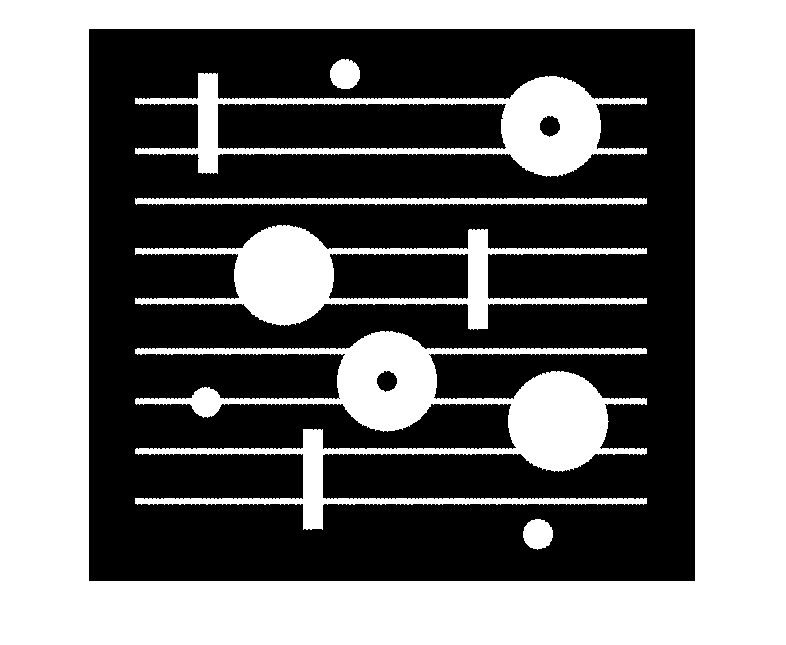

 imwrite(Image1a, 'Image1a_rotated.png')

% Problem 5-8
 Image1b_rotated = imrotate(Image1b, 15, 'bicubic', 'crop');
 imshow(Image1b_rotated);

 imwrite(Image1b, 'Image1b_rotated.png');


% Part 2 Morphology

% Problem 9-10

Image1c = imread('Image1c.tif');

disp(SE.Neighborhood);

   1   1   1   1   1
   1   1   1   1   1
   1   1   1   1   1
   1   1   1   1   1
   1   1   1   1   1



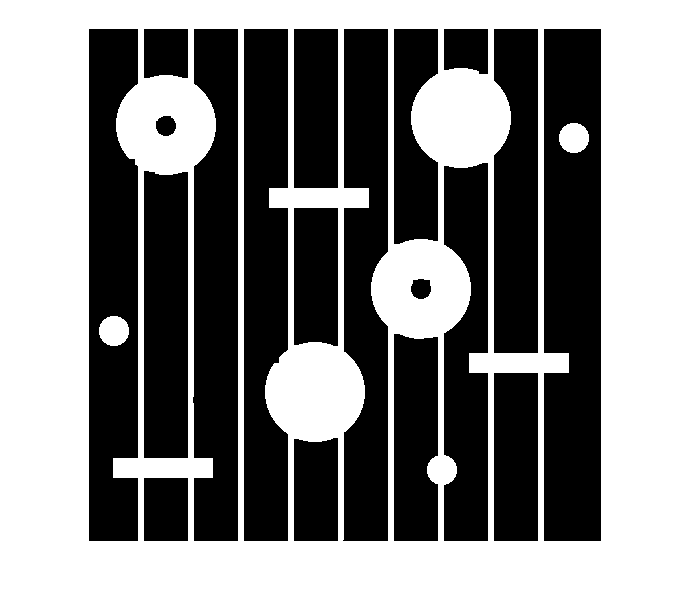

SE =strel('disk',3);
IM2 = imopen(Image1c, SE);
IM3 = imclose(IM2, SE);
imshow(IM3);

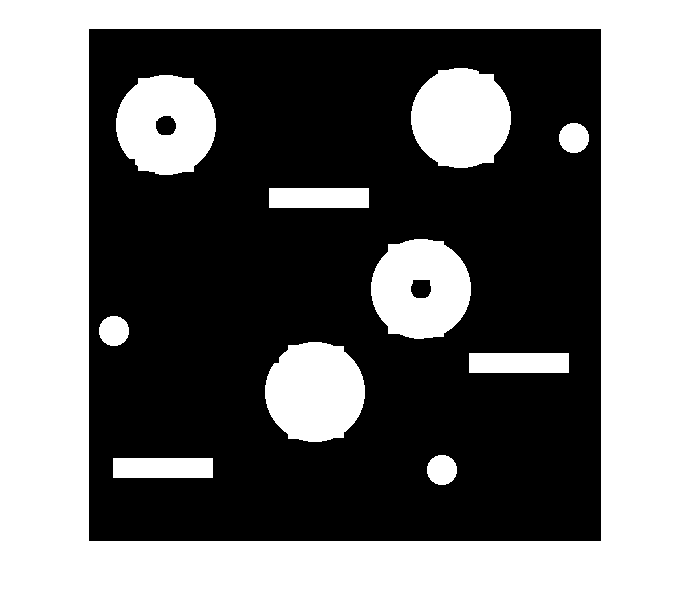

imwrite(IM3, 'Image1c_no_noise.png');

SE2 = strel('line', 6, 0);
IM4 = imopen(IM3, SE2);
IM5 = imclose(IM4, SE2);
imshow(IM5);

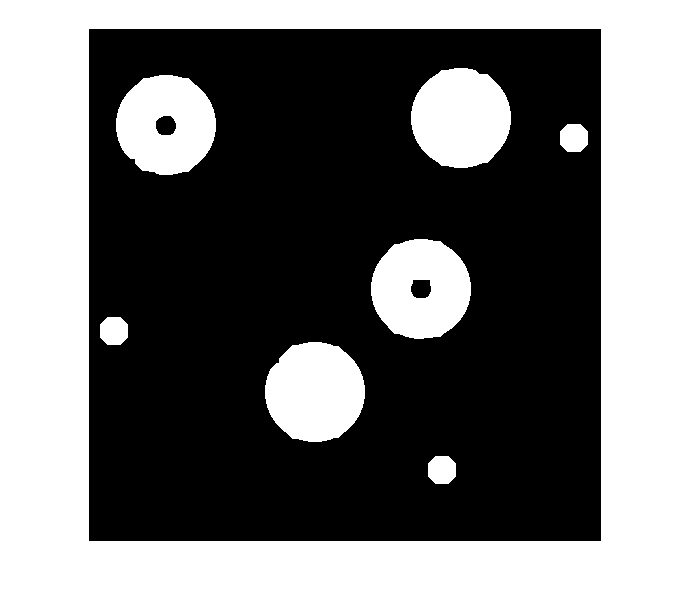

imwrite(IM5, 'Image1c_clean.png');

% Problem 11

%a
SE3 = strel('disk', 11);
IM6 = imopen(IM5, SE3);
IM7 = imclose(IM6, SE3);
figure; imshow(IM6);

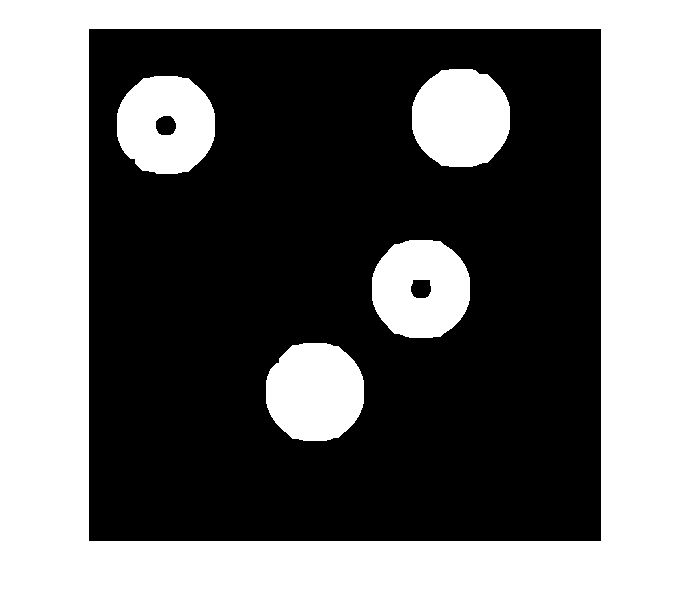

imwrite(IM6, 'Image1c_disks.png');

SE5 = strel('disk', 14);
IM7 = imopen(IM6, SE5);
figure; imshow(IM7);

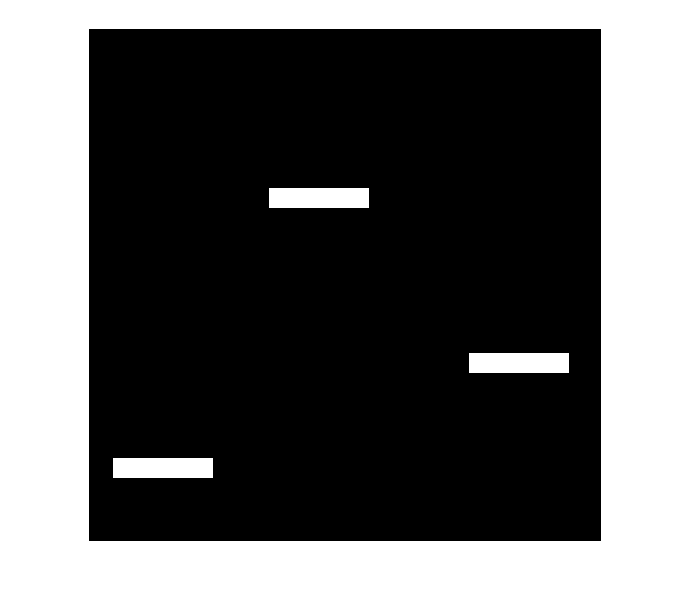


% b
MN = [20 100];
SE4 = strel('rectangle', MN);
IM8 = imopen(IM5, SE4);
IM9 = imclose(IM8, SE4);

figure; imshow(IM8);

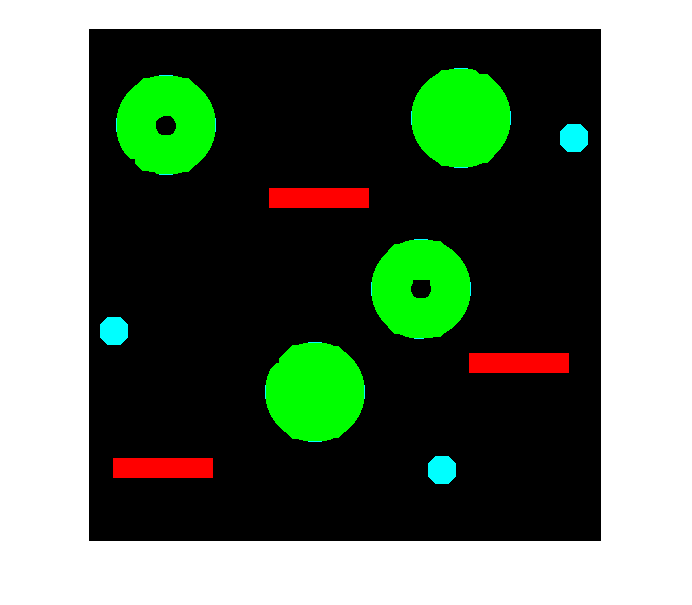

imwrite(IM8, 'Image1c_rectangles.png');

% c
[r, c] = size(Image1c);
RGB = zeros(r, c, 3);
RGB(:,:,1) = IM8;
RGB(:,:,2) = IM6;
RGB(:,:,3) = IM6 - IM7;

figure; imshow(RGB);

imwrite(RGB, 'RGB.png');


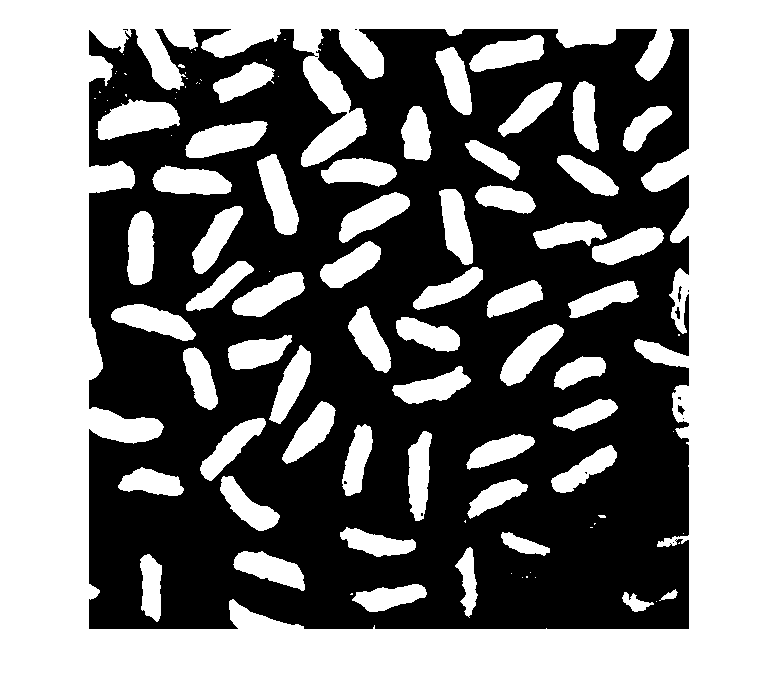

% Problem 12

rice=imread("rice-shaded.tif");
rice = im2double(rice);
rice_thresh = (rice > 0.2 & rice < 0.54);
rice_thresh = (rice_thresh == 0);
imshow(rice_thresh);

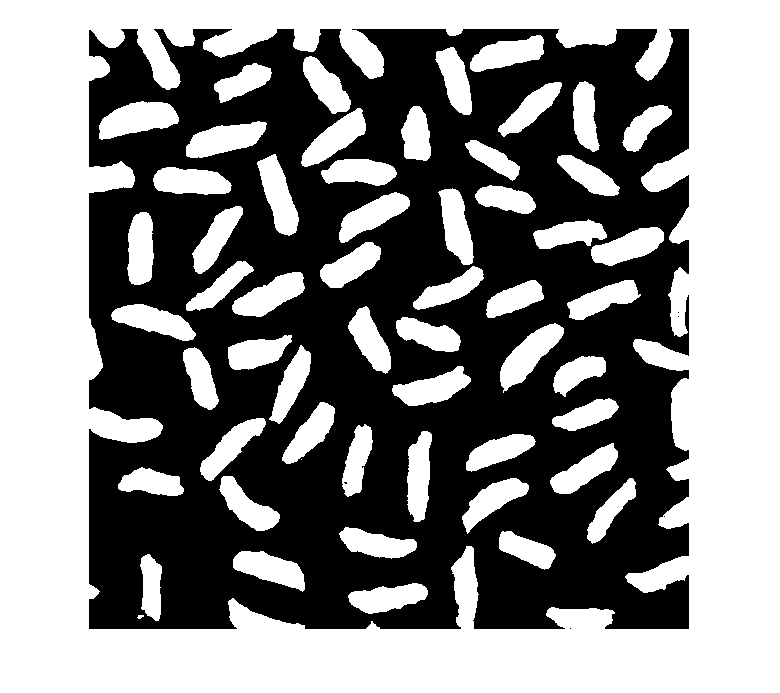

SE6 = strel('disk', 40);
rice_opened = imopen(rice, SE6);
% imshow(rice_opened);
rice_tophat= rice - rice_opened;
% imshow(rice_tophat);
rice_thresh1 = (rice_tophat > 0.23 & rice_tophat < 0.6);
imshow(rice_thresh1);


% Prt 3 Labelling and object features

% Problem 13
L = bwlabel(IM5);

Unrecognized function or variable 'IM5'.

imshow(L, [])
L = mat2gray(L);
imwrite(L, 'label.png');

% Problem 14
S = regionprops(L,'Perimeter','Area','EulerNumber');

for n=1:length(S)
    Perimeter(n)=S(n).Perimeter;
    Area(n)=S(n).Area;
    Euler(n)=S(n).EulerNumber;
end

LargeO=find(Area>3000)
Small0 = find(Perimeter<150)
Largest = find(Perimeter > 300 & (Euler == 1))

Perimeter(LargeO);

LargeO_Im=zeros(r,c);

for n=1:length(LargeO)
    LargeO_Im(L==LargeO(n))=1;
end

% Problem 15
BW2 = bwareafilt(logical(mat2gray(L)), [3000 10000]);
imshow(BW2)
imwrite(BW2, 'Largeobjects.png');

hist(Perimeter)

% Counting bricks

in_1 = imread("brick1.jpg");
in_2 = imread("brick2.jpg");
in_3 = imread("brick3.jpg");

[bild_1,nofr ]= CountBrickRows(in_1)

bild_1 = 940×1498×3 uint8 array
bild_1(:,:,1) =

   128   132   120   112   105    97    89   108   116   121   128   127   131   142   140   127   129   142   149   147   152   151   149   152   154   147   141   138   114   115   114    84    66    90   112    81    66    58    66    68    62    64    70    62    62    60    84   114   123   128   133   122   147   151   146   157   163   160   159   159   152   160   149   119    98    84    72    75    72    78    87    89    90    98   103   113   105   112   135   120   156   186   187   173   170   178   193   186   182   191   191   196   186   195   193   190   192   188   186   188   191   184   181   176   168   169   175   186   186   185   181   177   184   182   184   178   173   173   177   181   174   174   188   180   181   183   178   181   167   171   186   185   174   165   162   184   198   203   206   193   187   190   190   178   182   193   185   174   170   167   157   173   185   173   169   173   171   172   

nofr = 12

[bild_2,nofr ] = CountBrickRows(in_2)

bild_2 = 817×1418×3 uint8 array
bild_2(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

nofr = 10

[bild_3,nofr ] = CountBrickRows(in_3)

bild_3 = 1024×1596×3 uint8 array
bild_3(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    15   212   214   219   201   191   196   196   202   205   204   212   225   231   211   200   210   215   211   215   212   213   226   217   197   203   205   203   207   209   202   206   209   212   215   195   180   200   234   242   227   221   224   228   225   220   212   205   200   196  

nofr = 10

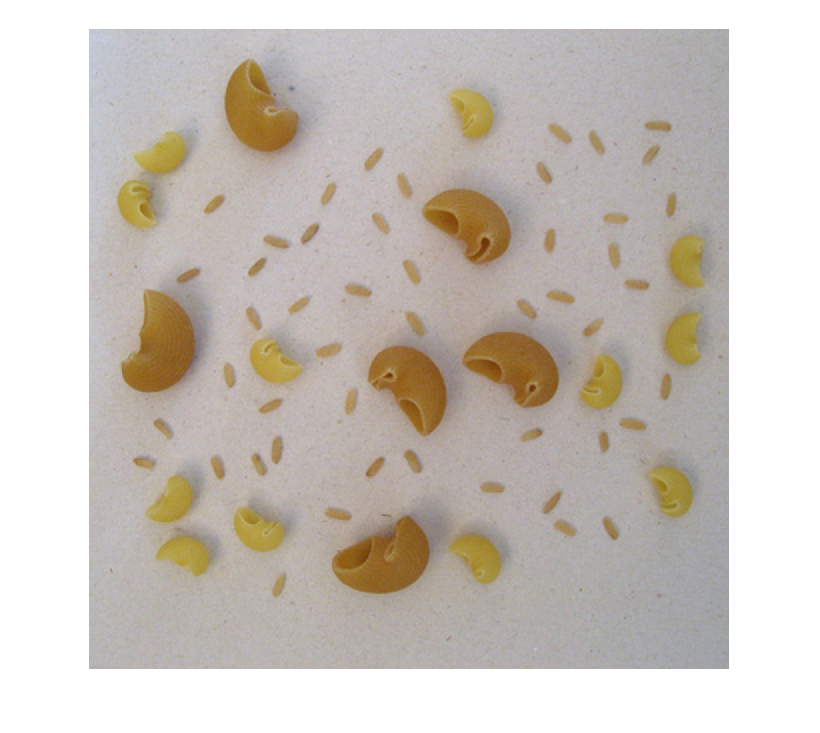

% Counting objects
clear

in_1 = imread("MacnRice1.tif");
imshow(in_1)

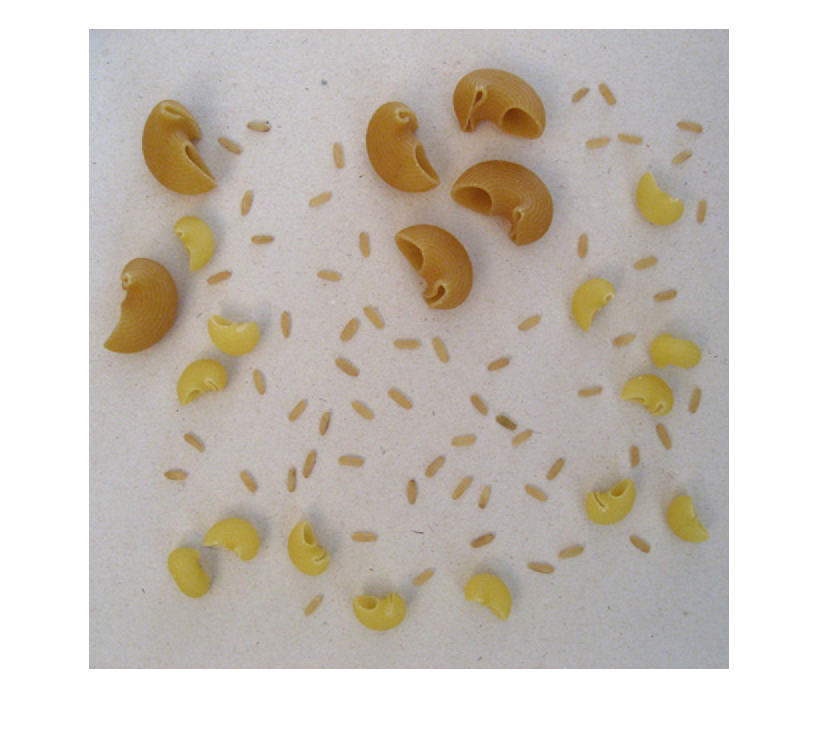

in_2 = imread("MacnRice2.tif");
imshow(in_2)

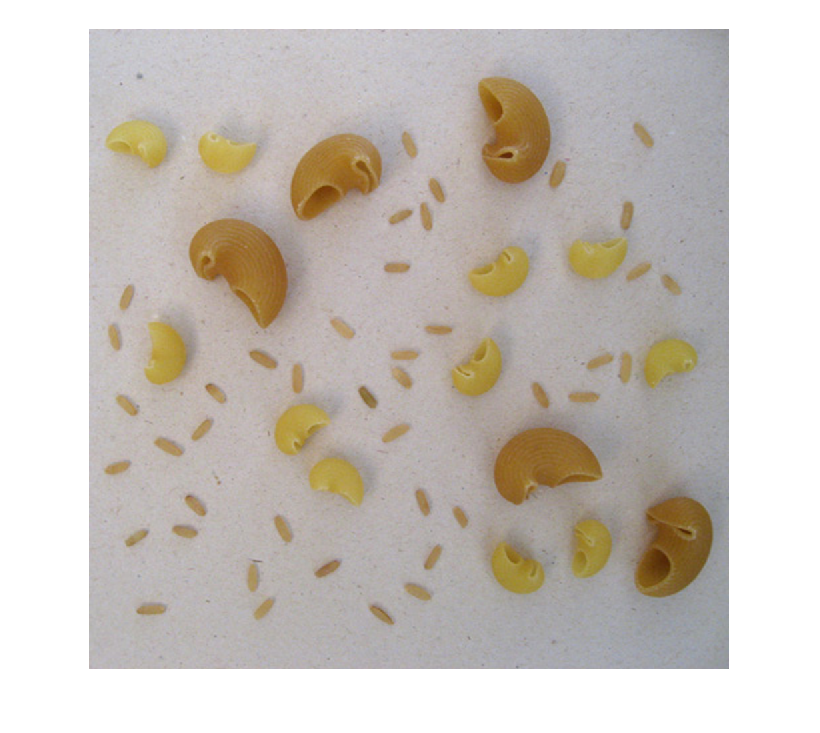

in_3 = imread("MacnRice3.tif");
imshow(in_3)

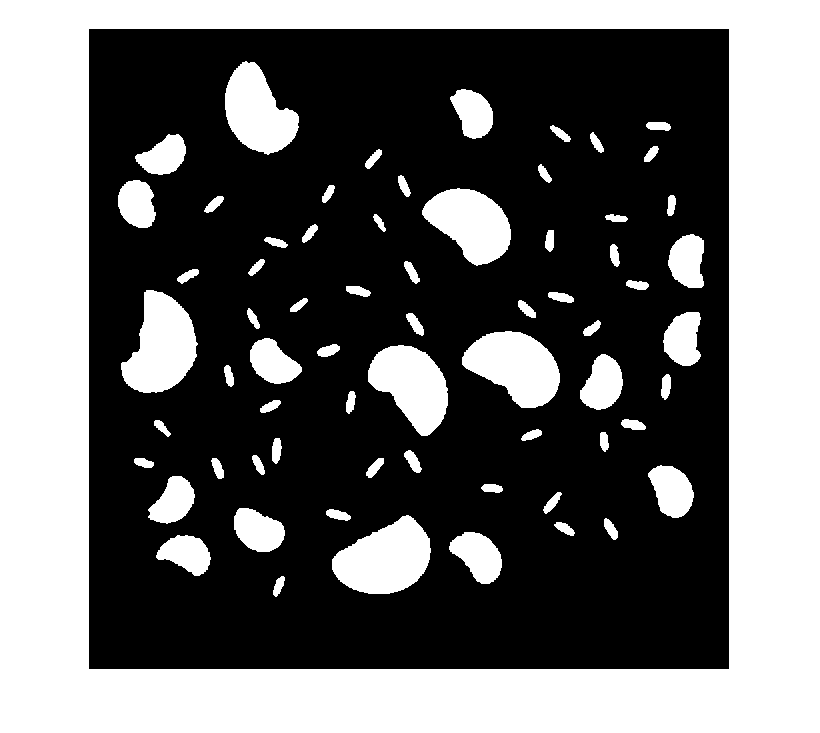

    48

    12

     6




[IMG1, noRice, noSmallMacs, noLargeMacs] = CountObjects(in_1);

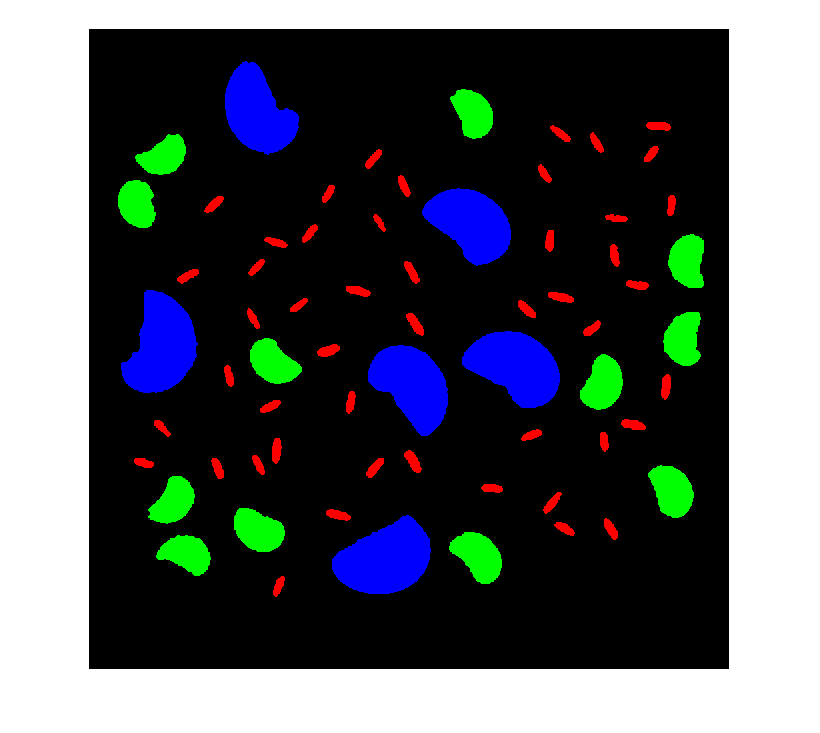

imshow(IMG1);

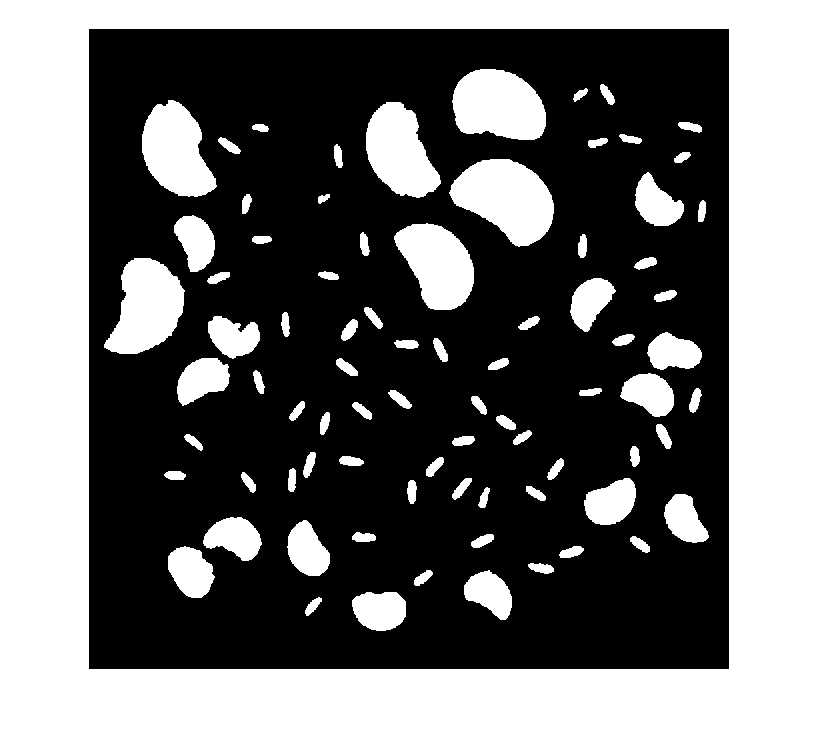

    60

    14

     6




[IMG2, noRice, noSmallMacs, noLargeMacs] = CountObjects(in_2);

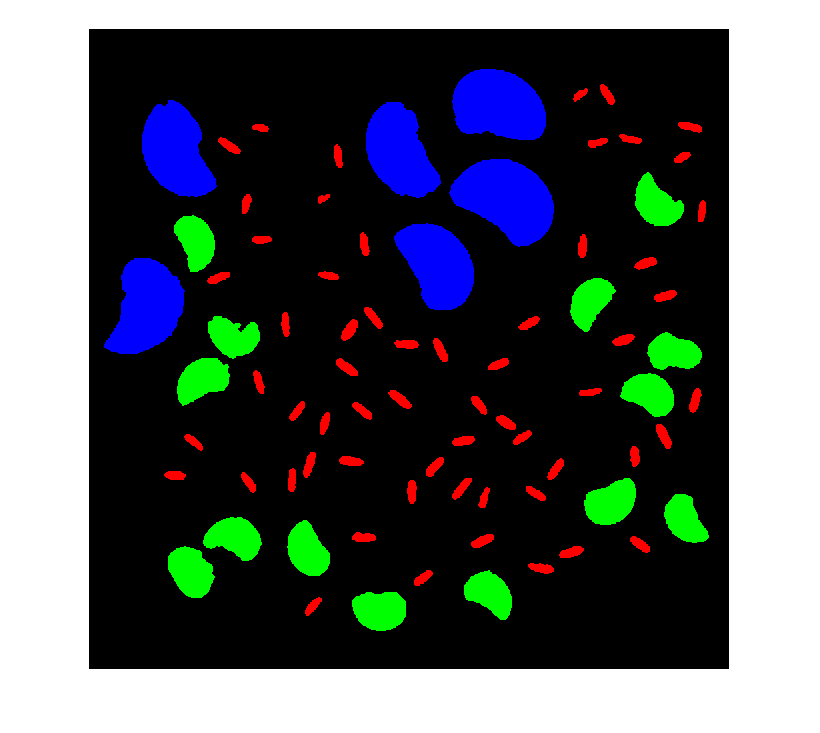

imshow(IMG2);

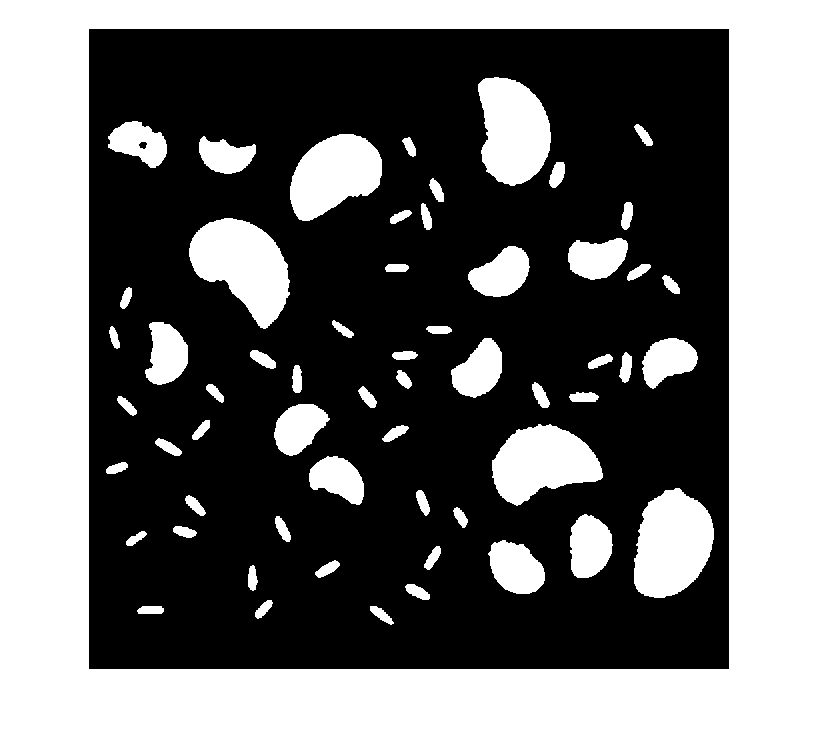

    42

    11

     5




[IMG3, noRice, noSmallMacs, noLargeMacs] = CountObjects(in_3);

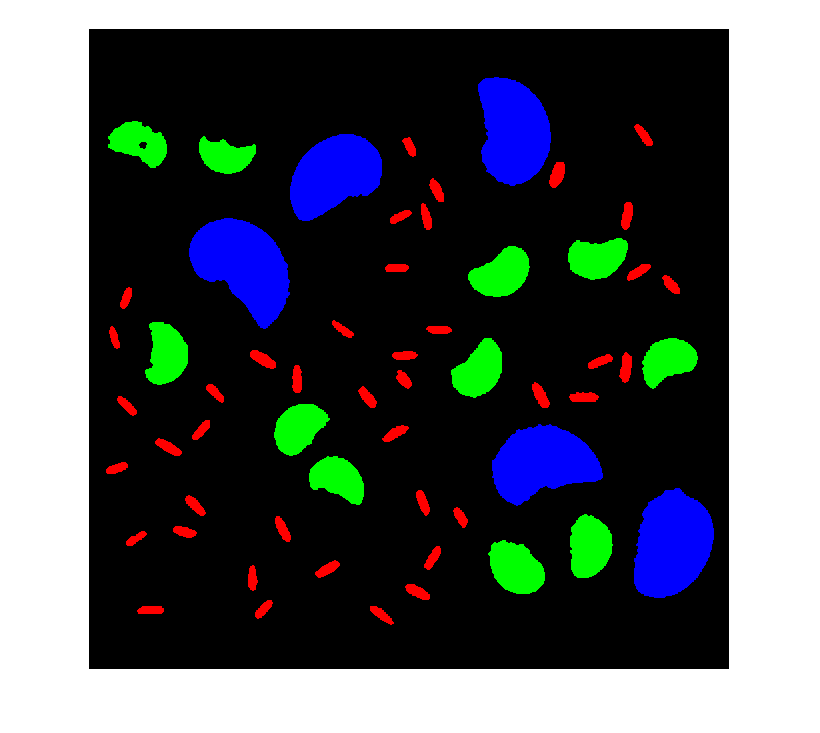

imshow(IMG3);